## **System + data**

% Define system components
oqpskmod = comm.OQPSKModulator('BitInput', true);
oqpskdemod = comm.OQPSKDemodulator('BitOutput', true);
channel = comm.AWGNChannel('EbNo', 20, 'BitsPerSymbol', 2);
errorRate = comm.ErrorRate("ReceiveDelay",4);

span = 4;                 % Filter span (number of symbols)
samplesPerSymbol = 8;      % Samples per symbol
decimation=4;
rolloff = 0.5;               % Rolloff factor
fs=1e7;

txFilter = comm.RaisedCosineTransmitFilter( ...
    'Shape','Square root',...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'OutputSamplesPerSymbol', samplesPerSymbol);

rxFilter = comm.RaisedCosineReceiveFilter( ...
    'Shape','Square root',...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'InputSamplesPerSymbol', samplesPerSymbol, ...
    'DecimationFactor', decimation);

symbolSync = comm.SymbolSynchronizer(...
    'SamplesPerSymbol', samplesPerSymbol/decimation, ...
    'Modulation','OQPSK', ...
    'TimingErrorDetector','Gardner (non-data-aided)');

% Optimized Coarse Frequency Compensator (CFC)
CFC = comm.CoarseFrequencyCompensator( ...
    'Modulation', 'OQPSK', ...
    'SampleRate', fs, ...
    'FrequencyResolution', 1e4);  % Higher resolution for better accuracy

% Optimized Fine Frequency Compensator (FFC)
FFC = comm.CarrierSynchronizer( ...
    'Modulation', 'OQPSK', ...
    'SamplesPerSymbol', 2, ...
    'DampingFactor', 0.707, ...           % Critically damped for faster response
    'NormalizedLoopBandwidth', 0.1);    

% Frame setup
numFrames = 1;             % Number of frames to transmit
frameSize = 2^13;        % Size of payload (in bits) per frame
preambleLength = 13;         % Barker code length
barkerGen = comm.BarkerCode("Length", preambleLength, 'SamplesPerFrame', preambleLength-1);
barkerCode = (barkerGen() + 1) / 2; % Map [-1, 1] to [0, 1]
barkerLen=length(barkerCode);
% Generate multiple frames
txData = [];
for frameIdx = 1:numFrames
    % Generate payload for this frame
    payload = randi([0 1], frameSize-barkerLen, 1);

    % Create frame: [preamble | payload]
    frame = [barkerCode; payload];
    txData = [txData; frame]; %#ok<AGROW>
end

## Transmitter

% Modulate the signal
txSignal = oqpskmod(txData);

% Frame Offset 
frameOffset = frameSize*randi([1,2]); % Introduce random offset for testing
padding = zeros(frameOffset, 1);

txSignal = [padding; txSignal];

% Filter the signal at the transmitter (with upsampling)
txSignal = txFilter(txSignal);

## Receiver

% Pass the signal through the AWGN channel
rxSignal = channel(txSignal);

% Timing Offset
vfd = dsp.VariableFractionalDelay; cd = comm.ConstellationDiagram;
tau=0.5;
rxSignal=vfd(rxSignal,tau);

% Phase & Freq offset
pfo = comm.PhaseFrequencyOffset( ...
    PhaseOffset=42, ...
    FrequencyOffset=-6e4, ...
    SampleRate=fs);

rxSignal=pfo(rxSignal);

% Filter the signal at the Receiver (with downsampling)
rxSignal = rxFilter(rxSignal); 

% for index = 0:500
%     % Delay signal
%     tau_hat = index/500; 
%     delayedsig = vfd(rxSignal, tau_hat);
%     % Visualize constellation
%     cd(delayedsig); pause(0.1);
% end

### Symbol-Synchronize and Time Correction

% Apply symbol synchronization
rx_I_sync = real(symbolSync(real(rxSignal)));
rx_Q_sync = real(symbolSync(imag(rxSignal)));
minLength = min(length(rx_I_sync), length(rx_Q_sync));
rx_I_sync = rx_I_sync(1:minLength);
rx_Q_sync = rx_Q_sync(1:minLength);

rxSignal = rx_I_sync + 1j*rx_Q_sync;

### Carrier-Synchronize

% Apply Coarse Frequency Compensation (CFC)
rxSignal = step(CFC, rxSignal);

% Apply Fine Frequency Compensation (FFC)
rxSignal = step(FFC, rxSignal);

### Phase Correction & Frame-Synchronization

barkerSignal=oqpskmod(barkerCode);
[corr, lags] = xcorr(rxSignal, barkerSignal);
[~, maxIdx] = max(abs(corr));

delay = (txFilter.FilterSpanInSymbols+rxFilter.FilterSpanInSymbols)/2;
frameStart = lags(maxIdx)-1;

rxBarkerSignal = rxSignal(frameStart : frameStart + length(barkerSignal)-1);

% Calculate the phase shift using the ratio of sum(Im/Re)
conjProd = conj(rxBarkerSignal).* barkerSignal;  % Conjugate product between Barker and received signal

% Calculate the mean of Im/Re
ImRe = mean(imag(conjProd) ./ real(conjProd));

% Calculate phase shift
theta_p = atan(ImRe);  % Apply atan on the sum of Im/Re ratio

% Frame-Synchronized signal
rxSignal = rxSignal(frameStart:end);

% Phase Corrected Signal
rxSignal= rxSignal * exp(-1j * theta_p);

### Demodulering + BER

% rxData = oqpskdemod(rxSignal);
% errorStats = errorRate(txData,rxData);
% disp(["BER: ", errorStats(1)]);
% disp(["tx:", txData(1:20)']);
% disp(["rx:", rxData(1:20)']);

# Time-Series

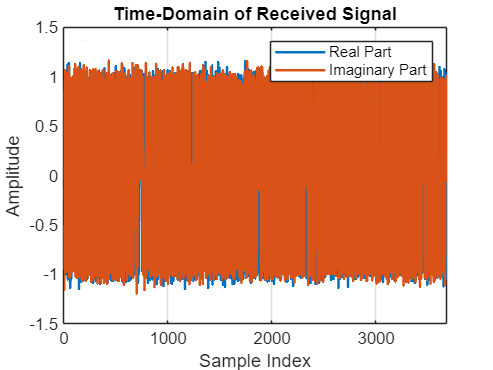

figure;
plot(real(rxSignal), 'LineWidth', 1.5,'DisplayName','Real Part');
hold on;
plot(imag(rxSignal), 'LineWidth', 1.5,'DisplayName','Imaginary Part');
title('Time-Domain of Received Signal');
xlabel('Sample Index');
ylabel('Amplitude');
legend();
xlim([0, length(rxSignal)]);
grid on;
hold off;

# PSD

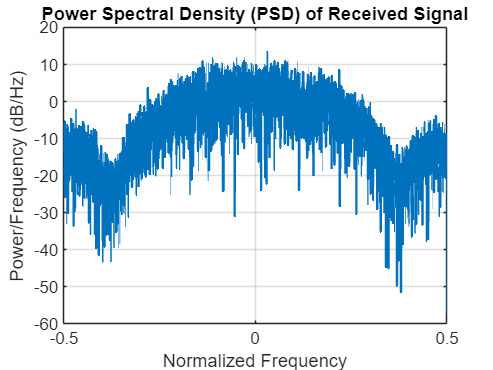

figure;
[psdValues, psdFreq] = periodogram(rxSignal, [], [], 1, 'centered');
plot(psdFreq, 10*log10(psdValues), 'LineWidth', 1.5);
title('Power Spectral Density (PSD) of Received Signal');
xlabel('Normalized Frequency');
ylabel('Power/Frequency (dB/Hz)');
grid on;

# Constellation

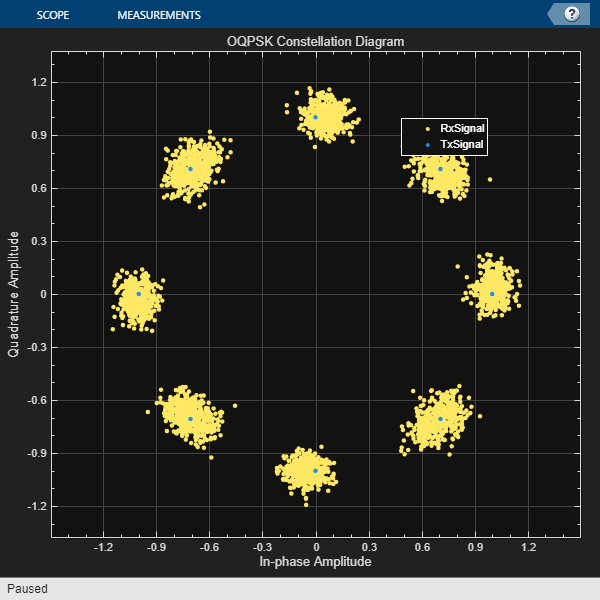

% Create a Constellation Diagram object
constDiagram = comm.ConstellationDiagram( ...
    'ReferenceConstellation', 0, ...
    'NumInputPorts', 2, ...
    'ShowLegend', true, ...
    'Title', 'OQPSK Constellation Diagram', ...
    'ChannelNames', {'RxSignal', 'TxSignal'});

% Visualize rxSignal and txSignal in the constellation diagram
constDiagram(rxSignal, oqpskmod(txData));

# Eye-Diagram

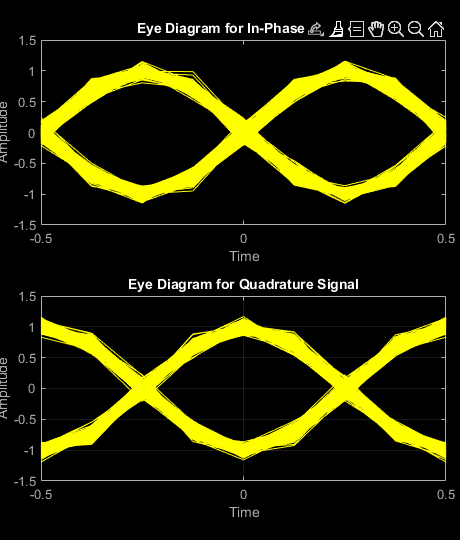

figure;
eyediagram(rxSignal, samplesPerSymbol);
%eyediagram(oqpskmod(txData), samplesPerSymbol);
xlabel('Time');
ylabel('Amplitude');
grid on;